clear all
close all
clc

%---------------- EDEIR ------------------

% replicate column 4 of table 4.4
% make sure the results generated by the new model is consistent with the old results
dynare EDEIR

Using 64-bit preprocessor
Starting Dynare (version 4.6.2).
Calling Dynare with arguments: none
Starting preprocessing of the model file ...
Found 12 equation(s).
Evaluating expressions...done
Computing static model derivatives (order 1).
Computing dynamic model derivatives (order 1).
Processing outputs ...
done
Preprocessing completed.


STEADY-STATE RESULTS:

A        		 0
c        		 0.110602
d        		 0.7442
h        		 0.00739062
i        		 -1.07949
k        		 1.22309
r        		 0.04
y        		 0.396416
lambda   		 1.72439
r_star_t 		 0.04
tb_y     		 0.0200257
ca_y     		 0

MODEL SUMMARY

  Number of variables:         12
  Number of stochastic shocks: 2
  Number of state variables:   5
  Number of jumpers:           4
  Number of static variables:  5


MATRIX OF COVARIANCE OF EXOGENOUS SHOCKS
Variables       eps_A     eps_r
eps_A        1.000000  0.000000
eps_r        0.000000  1.000000



THEORETICAL MOMENTS
VARIABLE         MEAN  STD. DEV.   VARIANCE
y              0.396

MODEL SUMMARY

  Number of variables:         12
  Number of stochastic shocks: 2
  Number of state variables:   5
  Number of jumpers:           4
  Number of static variables:  5


MATRIX OF COVARIANCE OF EXOGENOUS SHOCKS
Variables       eps_A     eps_r
eps_A        1.000000  0.000000
eps_r        0.000000  1.000000



THEORETICAL MOMENTS
VARIABLE         MEAN  STD. DEV.   VARIANCE
y              0.3964     0.1560     0.0243
c              0.1106     0.1092     0.0119
i             -1.0795     0.9933     0.9866
h              0.0074     0.1072     0.0115
tb_y           0.0200     0.2417     0.0584
ca_y           0.0000     0.2377     0.0565



MATRIX OF CORRELATIONS
Variables         y       c       i       h    tb_y    ca_y
y            1.0000  0.9932  0.0635  1.0000  0.2357  0.1869
c            0.9932  1.0000  0.1636  0.9932  0.1351  0.0867
i            0.0635  0.1636  1.0000  0.0635 -0.9547 -0.9684
h            1.0000  0.9932  0.0635  1.0000  0.2357  0.1869
tb_y         0.2357  0.

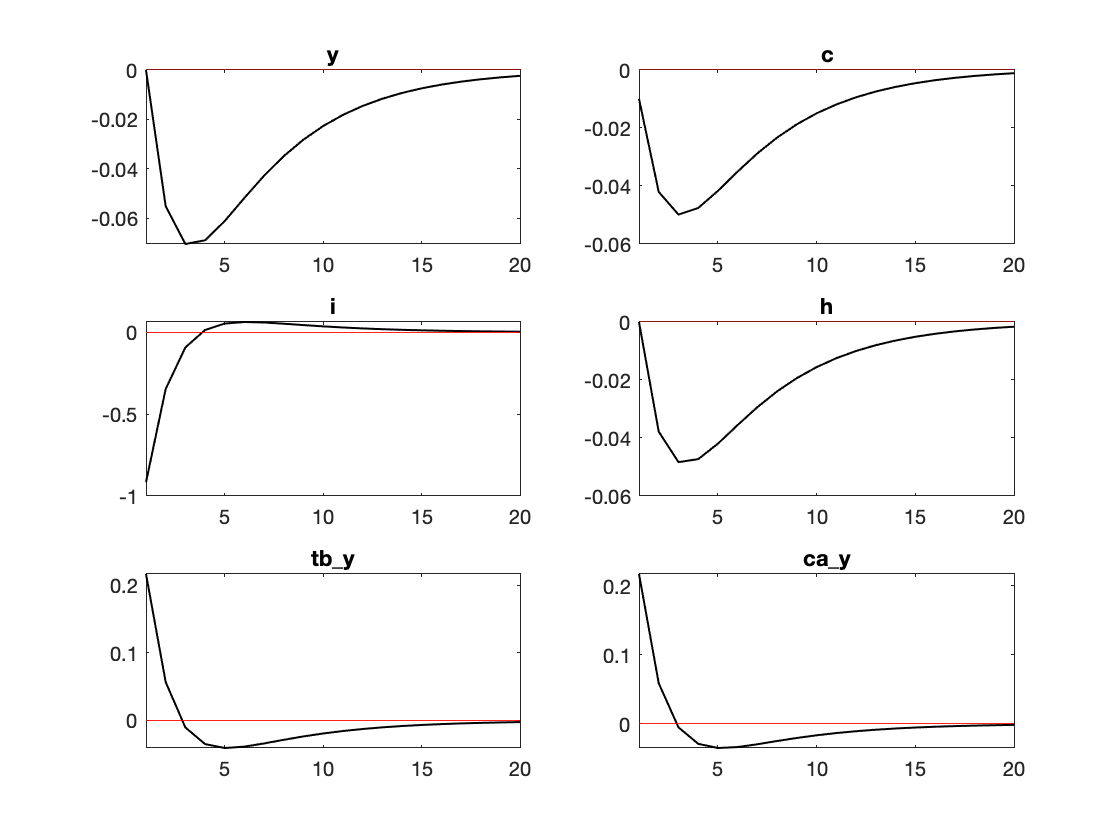


% turn off productivity shock and turn on interest rate shock
set_param_value('eta', 0);
set_param_value('sigma_mu', 0.012);

% set_param_value('eta', 0.0129);
% set_param_value('sigma_mu', 0.0);

% re-run the model
options_.irf = 20;
[info,oo_,options_,M_]=stoch_simul(M_,options_,oo_,var_list_);




%---------------- IDF --------------------

clear all
close all
clc
% replicate column 1 of table 4.4
% make sure the results generated by the new model is consistent with the old results
dynare IDF

Using 64-bit preprocessor
Starting Dynare (version 4.6.2).
Calling Dynare with arguments: none
Starting preprocessing of the model file ...
Found 14 equation(s).
Evaluating expressions...done
Computing static model derivatives (order 1).
Computing dynamic model derivatives (order 1).
Processing outputs ...
done
Preprocessing completed.



STEADY-STATE RESULTS:

c        		 0.110602
h        		 0.00739062
y        		 0.396416
i        		 -1.07949
k        		 1.22309
a        		 0
lambda   		 2.11473
util     		 -1.36835
d        		 0.7442
tb_y     		 0.0200257
ca_y     		 0
r        		 0.04
beta_fun 		 0.961538
eta      		 35.5771

MODEL SUMMARY

  Number of variables:         14
  Number of stochastic shocks: 2
  Number of state variables:   4
  Number of jumpers:           6
  Number of static variables:  5


MATRIX OF COVARIANCE OF EXOGENOUS SHOCKS
Variables           e      mu_t
e            1.000000  0.000000
mu_t         0.000000  1.000000



THEORETICAL MOMENTS
VARIABLE         MEAN  STD. DEV.   VARIANCE
y              0.3964     0.0307     0.0009
c              0.1106     0.0235     0.0006
i             -1.0795     0.0910     0.0083
h              0.0074     0.0211     0.0004
tb_y           0.0200     0.0155     0.0002
ca_y           0.0000     0.0146     0.0002



MATRIX OF CORRELATIONS
Variables         y      

MODEL SUMMARY

  Number of variables:         14
  Number of stochastic shocks: 2
  Number of state variables:   4
  Number of jumpers:           6
  Number of static variables:  5


MATRIX OF COVARIANCE OF EXOGENOUS SHOCKS
Variables           e      mu_t
e            1.000000  0.000000
mu_t         0.000000  1.000000



THEORETICAL MOMENTS
VARIABLE         MEAN  STD. DEV.   VARIANCE
y              0.3964     0.1622     0.0263
c              0.1106     0.1162     0.0135
i             -1.0795     1.0224     1.0454
h              0.0074     0.1115     0.0124
tb_y           0.0200     0.2513     0.0632
ca_y           0.0000     0.2470     0.0610



MATRIX OF CORRELATIONS
Variables         y       c       i       h    tb_y    ca_y
y            1.0000  0.9884  0.0684  1.0000  0.2254  0.1724
c            0.9884  1.0000  0.2005  0.9884  0.0912  0.0388
i            0.0684  0.2005  1.0000  0.0684 -0.9562 -0.9709
h            1.0000  0.9884  0.0684  1.0000  0.2254  0.1724
tb_y         0.2254  0.

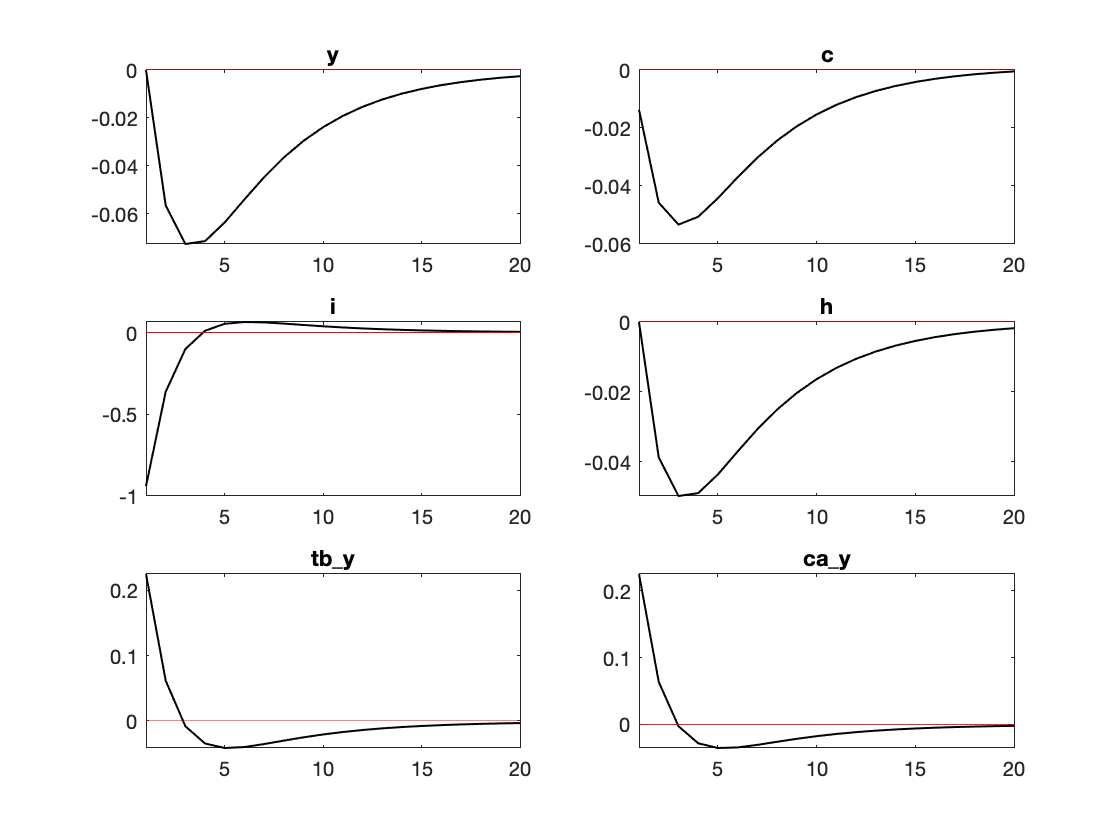


% turn off productivity shock and turn on interest rate shock
set_param_value('sigma_tfp', 0);
set_param_value('sigma_mu',  0.012);

% set_param_value('sigma_tfp', 0.0129);
% set_param_value('sigma_mu',  0.0);

% re-run the model
options_.irf = 20; 
[info,oo_,options_,M_]=stoch_simul(M_,options_,oo_,var_list_);